## **Data Augmentation**

Data augmentation is used to improve network accuracy by randomly transforming the original data during training. By using data augmentation, you can add more variety to the training data without actually having to increase the number of labeled training samples.

- Color jitter augmentation in HSV space

- Random horizontal flip

- Random scaling by 10 percent

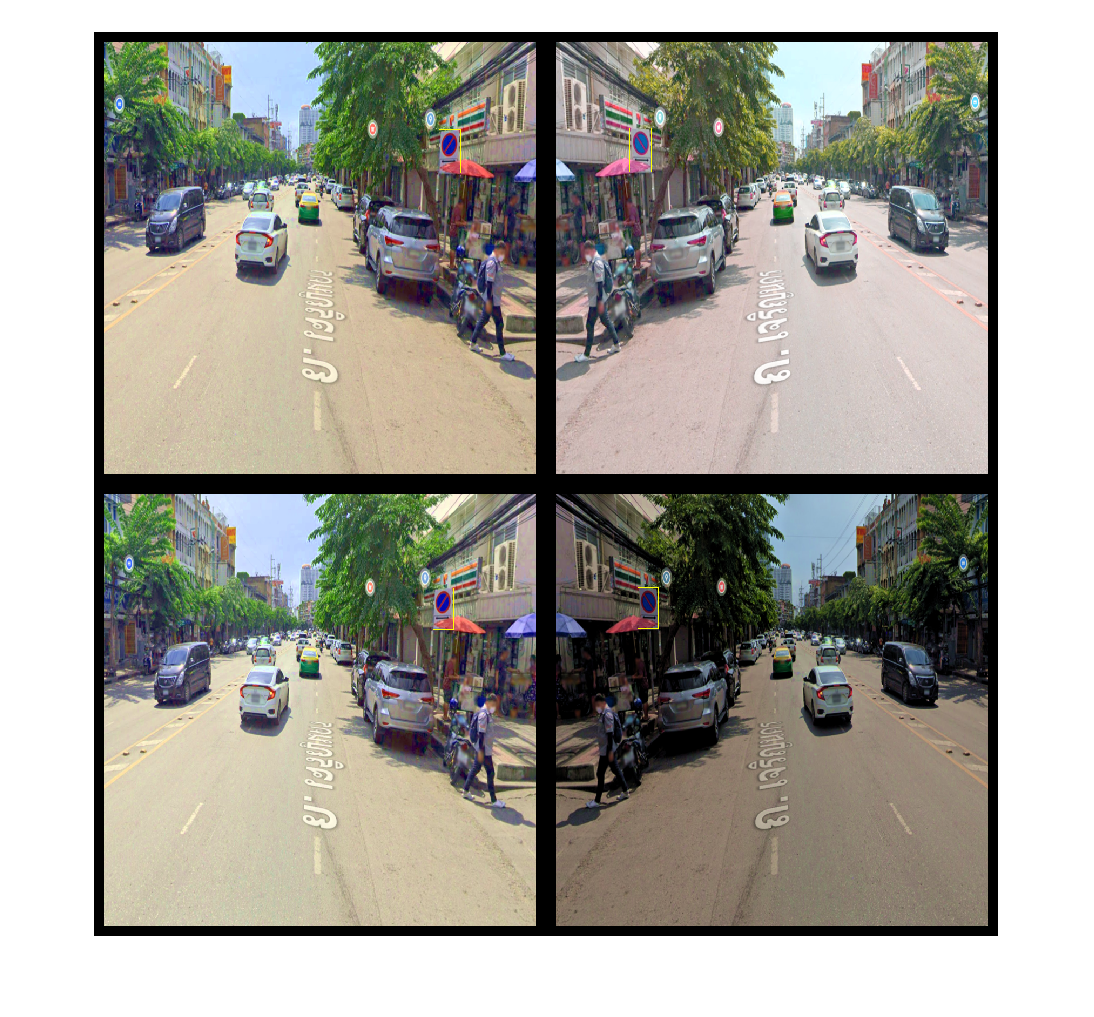

augmentedTrainingData = transform(trainingData,@augmentData);
% Visualize the augmented images.
augmentedData = cell(4,1);
for k = 1:4
    data = read(augmentedTrainingData);
    augmentedData{k} = insertShape(data{1},'Rectangle',data{2});
    reset(augmentedTrainingData);
end
figure
montage(augmentedData,'BorderSize',10)

## Create parameter for training (inputSize, anchors, lgraph) (only for frist train)

inputSize = [800 800 3];
%6,11 Class inputSize = [300 400 3];
numAnchors =6;
[anchors, meanIoU] = estimateAnchorBoxes(augmentedTrainingData, numAnchors)

anchors =    117    69
   169   154
    47    32
   322   206


meanIoU = 0.6361

numClasses = 1;
%numClasses = 6;
%numClasses = 11;

lgraph = fasterRCNNLayers(inputSize,numClasses,anchors,"resnet18");
analyzeNetwork(lgraph);

## First Training

options = trainingOptions('sgdm',...
    'MaxEpochs',30,...
    'VerboseFrequency',50,...
    'MiniBatchSize',1,...
    'InitialLearnRate',1e-3,...
    'CheckpointPath',tempdir,...
    'ValidationData',validationData, ...
    'ExecutionEnvironment','gpu');

    [detector, info] = trainFasterRCNNObjectDetector(augmentedTrainingData,lgraph,options, ...
        'NegativeOverlapRange',[0 0.5], ...
        'PositiveOverlapRange',[0.68 1]);

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* circle
* crossRoad
* diamond
* octagon
* rectangle
* triangle

Initializing input data normalization.
|==========================================================================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Validation  |  Validation  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|===================================================================================================================================================================================

save('Detector\1ClassE30_Over.mat','detector');

## Training from pretrained

pretrained = load('Detector\1ClassE17_Over.mat');  %load ตัวที่อยากจะเอามา train ต่อ
pretrained = pretrained.detector3;  %ดูด้วยว่า .detector ถูกเปล่าจาก workspace
options = trainingOptions('sgdm',...
    'MaxEpochs',4,...
    'VerboseFrequency',50,...
    'MiniBatchSize',1,...
    'InitialLearnRate',1e-3,...
    'CheckpointPath',tempdir,...
    'ValidationData',validationData, ...
    'ExecutionEnvironment','gpu');
[detector2, info] = trainFasterRCNNObjectDetector(augmentedTrainingData,pretrained,options, ...
        'NegativeOverlapRange',[0 0.5], ...
        'PositiveOverlapRange',[0.7 1]);

*************************************************************************
Training a Faster R-CNN Object Detector for the following object classes:

* trafficSign

Initializing input data normalization.
|==========================================================================================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Mini-batch  |  RPN Mini-batch  |  RPN Mini-batch  |  Validation  |  Validation  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |     Loss     |   Accuracy   |     RMSE     |     Accuracy     |       RMSE       |     Loss     |   Accuracy   |     RMSE     |      Rate       |
|==========================================================================================================================================================================================|
|       1 |           1 |       00:01:08 

|       1 |          50 |       00:06:55 |       0.0814 |       99.65% |         0.10 |           99.22% |             0.30 |       0.1947 |       99.57% |         0.09 |          0.0010 |
|       1 |         100 |       00:12:53 |       0.3269 |       99.65% |         0.02 |           97.66% |             0.86 |       0.1911 |       99.70% |         0.08 |          0.0010 |
|       1 |         150 |       00:18:47 |       0.0814 |      100.00% |         0.06 |           99.22% |             0.34 |       0.1917 |       99.69% |         0.09 |          0.0010 |
|       1 |         200 |       00:24:34 |       0.0417 |       99.95% |         0.10 |           99.22% |             0.16 |       0.1881 |       99.76% |         0.08 |          0.0010 |
|       1 |         250 |       00:30:29 |       0.0656 |       99.85% |         0.08 |           99.22% |             0.25 |       0.2010 |       99.77% |         0.08 |          0.0010 |
|       1 |         300 |       00:36:23 |       0.2439

save('Detector\1ClassE30_Over.mat','detector2');

## Load pretrained for test or Evaluate

pretrained2 = load('Detector\Hope.mat');
detector3 = pretrained2.detector3; %ดูด้วยว่า .detector ถูกเปล่าจาก workspace

## **Test pretrained**

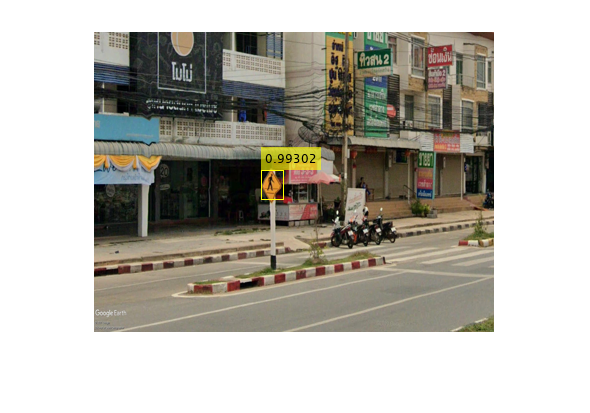

%I = imread('Image_Set_1\Image5.png');
I = imread('TrafficSignDataset\26.png');
k=imresize(I,[300,400]);
%[bboxes,scores] = detect(detector3,k);
[bboxes,scores] = detect(detector3,k,'Threshold',0.75);
I = insertObjectAnnotation(k,'rectangle',bboxes,scores);
figure
imshow(I)

## **Evaluate Detector Using Test Set**

detectionResults = detect(detector3,testData,'MinibatchSize',4);   
[ap,recall,precision] = evaluateDetectionPrecision(detectionResults, testData);

## Plot Precision Recall Graph

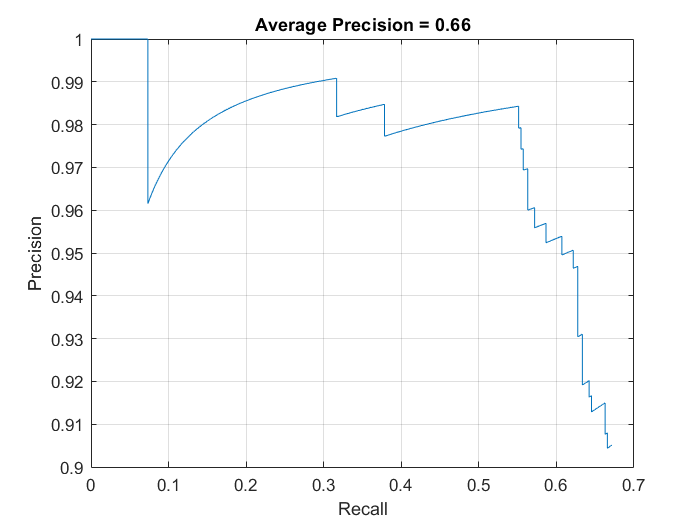

figure
% 6,11 Class i= % class ที่อยาก check เช่น 1,2,3...;
% 6,11 Class plot(recall{i},precision{i})
plot(recall,precision)
xlabel('Recall')
ylabel('Precision')
grid on
title(sprintf('Average Precision = %.2f',ap))

% 6,11 Class title(sprintf('Average Precision = %.2f',ap(i,1)))


## **Function for AugmentData**

function data = augmentData(A)
data = cell(size(A));
for ii = 1:size(A,1)
    I = A{ii,1};
    bboxes = A{ii,2};
    labels = A{ii,3};
    sz = size(I);

    if numel(sz) == 3 && sz(3) == 3
        I = jitterColorHSV(I,...
            'Contrast',0.0,...
            'Hue',0.1,...
            'Saturation',0.2,...
            'Brightness',0.2);
    end
    
    % Randomly flip image.
    tform = randomAffine2d('XReflection',true,'Scale',[1 1.1]);
    rout = affineOutputView(sz,tform,'BoundsStyle','centerOutput');
    I = imwarp(I,tform,'OutputView',rout);
    
    % Apply same transform to boxes.
    [bboxes,indices] = bboxwarp(bboxes,tform,rout,'OverlapThreshold',0.25);
    labels = labels(indices);
    
    % Return original data only when all boxes are removed by warping.
    if isempty(indices)
        data(ii,:) = A(ii,:);
    else
        data(ii,:) = {I, bboxes, labels};
    end
end
end